# Link Strength Analysis

## Choosing the multistability for which the analysis is to be performed

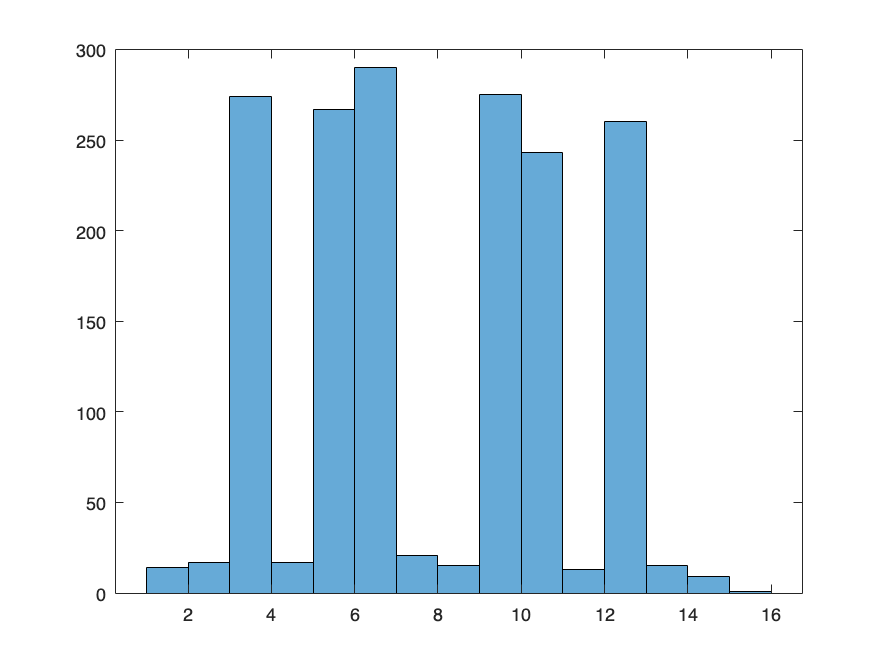

% The analysis is performed for one multistability at a time. Here,
% it is done for monostable solutions. To perform for bistable 
% solutions, 'solution_1' everywhere is to be replaced by 
% 'solution_2'. Also, only solution_1 and solution_2 have been 
% performed in the paper.
x = phase_classification_in_phase_order.solution_1;
binc = 1:(length(all_phases.solution_1)+1);
counts = histogram(x,binc);

result = [binc(1:end-1);counts.Values];
result = sortrows(result',2,'descend');
% choosing only the high frequent monostable phases out of the 
% possible - 16 phases. For bistable phases - 16*16 phases, 
% are possible.
result = result(result(:,2)>0.10*max(result(:,2)),:);
result = array2table(result');
result.Properties.VariableNames = cellstr(...
    all_phases.solution_1(table2array(result(1,:)),:)');

% For each of the shortlisted phases, the corresponding parameter sets
% enabling them are also shortlisted and on them, the link strength
% analysis is performed.
for i = 1:size(result,2)
    new_file = horzcat(organized_bool_solution_file.solution_1,...
        phase_classification_in_phase_order.solution_1);
    params = new_file(new_file(:,end)==table2array(result(1,i)));
    % shortlisted parameter sets for the respective phase
    parameter_file_new = parameter_file(params,:);
    [link_strengths,link_strength_values] = LS_analysis(params,...
        parameter_file_new);
    % storing the link strength values and respective parameter sets
    final_link_strengths.(strcat("solution_1_param_",num2str(...
        table2array(result(1,i))))) = link_strengths;
    final_parameter_sets.(strcat("solution_1_param_",num2str(...
        table2array(result(1,i))))) = parameter_file_new;
    final_link_strength_values.(strcat("solution_1_param_",num2str(...
        table2array(result(1,i))))) = link_strength_values;
end

## Functions used in the script

function [link_strengths,link_strength_values] = LS_analysis(params,...
    parameter_file)
% initializing count at 0 for all the 12 edges of TTr
x_CA = 0; x_AC = 0;
x_CB = 0; x_BC = 0;
x_DA = 0; x_AD = 0;
x_DB = 0; x_BD = 0;
x_CD = 0; x_DC = 0;
x_AB = 0; x_BA = 0;
% iterating over all shortlisted parameter sets
for l = 1:length(params)
    % defining link strength for each of the 12 edges
    CA = parameter_file.Num_of_CToA(l)/(parameter_file.Inh_of_CToA(l)...
        *parameter_file.Trd_of_CToA(l));
    AC = parameter_file.Num_of_AToC(l)/(parameter_file.Inh_of_AToC(l)...
        *parameter_file.Trd_of_AToC(l));
    CB = parameter_file.Num_of_CToB(l)/(parameter_file.Inh_of_CToB(l)...
        *parameter_file.Trd_of_CToB(l));
    BC = parameter_file.Num_of_BToC(l)/(parameter_file.Inh_of_BToC(l)...
        *parameter_file.Trd_of_BToC(l));
    DA = parameter_file.Num_of_DToA(l)/(parameter_file.Inh_of_DToA(l)...
        *parameter_file.Trd_of_DToA(l));
    AD = parameter_file.Num_of_AToD(l)/(parameter_file.Inh_of_AToD(l)...
        *parameter_file.Trd_of_AToD(l));
    DB = parameter_file.Num_of_DToB(l)/(parameter_file.Inh_of_DToB(l)...
        *parameter_file.Trd_of_DToB(l));
    BD = parameter_file.Num_of_BToD(l)/(parameter_file.Inh_of_BToD(l)...
        *parameter_file.Trd_of_BToD(l));
    CD = parameter_file.Num_of_CToD(l)/(parameter_file.Inh_of_CToD(l)...
        *parameter_file.Trd_of_CToD(l));
    DC = parameter_file.Num_of_DToC(l)/(parameter_file.Inh_of_DToC(l)...
        *parameter_file.Trd_of_DToC(l));
    AB = parameter_file.Num_of_AToB(l)/(parameter_file.Inh_of_AToB(l)...
        *parameter_file.Trd_of_AToB(l));
    BA = parameter_file.Num_of_BToA(l)/(parameter_file.Inh_of_BToA(l)...
        *parameter_file.Trd_of_BToA(l));
    if CA>AC
        x_CA = x_CA + 1;
    else x_AC = x_AC + 1;
    end
    if CB>BC
        x_CB = x_CB + 1;
    else x_BC = x_BC + 1;
    end
    if DA>AD
        x_DA = x_DA + 1;
    else x_AD = x_AD + 1;
    end
    if DB>BD
        x_DB = x_DB + 1;
    else x_BD = x_BD + 1;
    end
    if CD>DC
        x_CD = x_CD + 1;
    else x_DC = x_DC + 1;
    end
    if AB>BA
        x_AB = x_AB + 1;
    else x_BA = x_BA + 1;
    end
end
% storing the link strength values in the order as given below
link_strength_values = [AB,BA,BC,CB,CD,DC,DA,AD,AC,CA,DB,BD];
link_strength_values = array2table(link_strength_values);
link_strength_values.Properties.VariableNames = ...
    ["AB","BA","BC","CB","CD","DC","DA","AD","AC","CA","DB","BD"];
link_strengths = [x_AB,x_BC,x_CD,x_DA,x_AC,x_DB;...
    x_BA,x_CB,x_DC,x_AD,x_CA,x_BD];
link_strengths(3:4,:) = link_strengths./length(params);
link_strengths = array2table(link_strengths);
link_strengths.Properties.VariableNames = ...
    {'AB|BA','BC|CB','CD|DC','DA|AD','AC|CA','DB|BD'};
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above, for every phase an dover all the shortlisted
% parameter sets, calculates link strengths, compares between 
% (eg: AB|BA) opposing edges, keeps a count of the same and 
% finally stores in a fixed
% order of the 12 edges as mentioned above.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%